# ouverture image

## flitre trouge

p = 18

p = 19

N = 319

l = "319"

l = "319.jpg"

N = 320

l = "320"

l = "320.jpg"

p = 20

N = 321

l = "321"

l = "321.jpg"

N = 322

l = "322"

l = "322.jpg"

N = 323

l = "323"

l = "323.jpg"

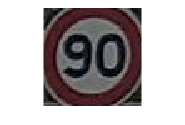

for p=18:20
    p
    dsx = string(p);
    dsx = dsx.append('.jpg');
route70 = imread(dsx);
route70 = im2double(route70);
figure(1)
imshow(route70)

%conversion en hsv
route70hsv = rgb2hsv(route70);

hue = route70hsv(:,:,1);
sat = route70hsv(:,:,2);
val = route70hsv(:,:,3);

%imshow(hue)
%imshow(sat)
%imshow(val)

masque = zeros(size(hue));
masque (hue<0.06 & hue>=0 & sat > 0.15) = 1;
masque (hue>0.90 & hue<=1 & sat > 0.15) = 1;

SE = strel("disk",2);

masque = imerode(masque,SE);
masque = imdilate(masque,SE);

imshow(masque)
masque = 1-masque;

Rmin = 10;
Rmax = 800;

[centersBright, radiiBright] = imfindcircles(masque,[Rmin Rmax],'Sensitivity',0.935);
viscircles(centersBright, radiiBright,'Color','b');

Roundcenter = round(centersBright);
Roundradius = round(radiiBright);

S = cell(length(Roundradius),1);

for i=1:length(Roundradius)
    A =  zeros(Roundradius(i)*2);
    for j=1:3
        S{i}(:,:,j) = A;
    end
end
for i=1:length(Roundradius)
    S{i} = route70(Roundcenter(i,2)-round(1.3*Roundradius(i)):Roundcenter(i,2)+round(1.3*Roundradius(i)) ...
                   ,Roundcenter(i,1)-round(1.3*Roundradius(i)):Roundcenter(i,1)+round(1.3*Roundradius(i)), ...
                   :);
end

for k=1:length(S)
    N = N+1
    l = string(N)
    l = l.append('.jpg')
    imshow(S{k})
    imwrite(S{k},l,"jpg")
end
end